clear
clc

addpath("/Users/louieburns/Downloads/CW2_Complete_Robot_URDF_2025_V6 3/urdf")
savepath % Save filepath for next time

Robot = importrobot('CW2_Complete_Robot_URDF_2025_V6.urdf');
showdetails(Robot)

--------------------
Robot: (1 bodies)

 Idx      Body Name           Joint Name           Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------           ----------           ----------      ----------------   ----------------
   1        Library        Library_Fixed                fixed          Base_Link(0)   
--------------------


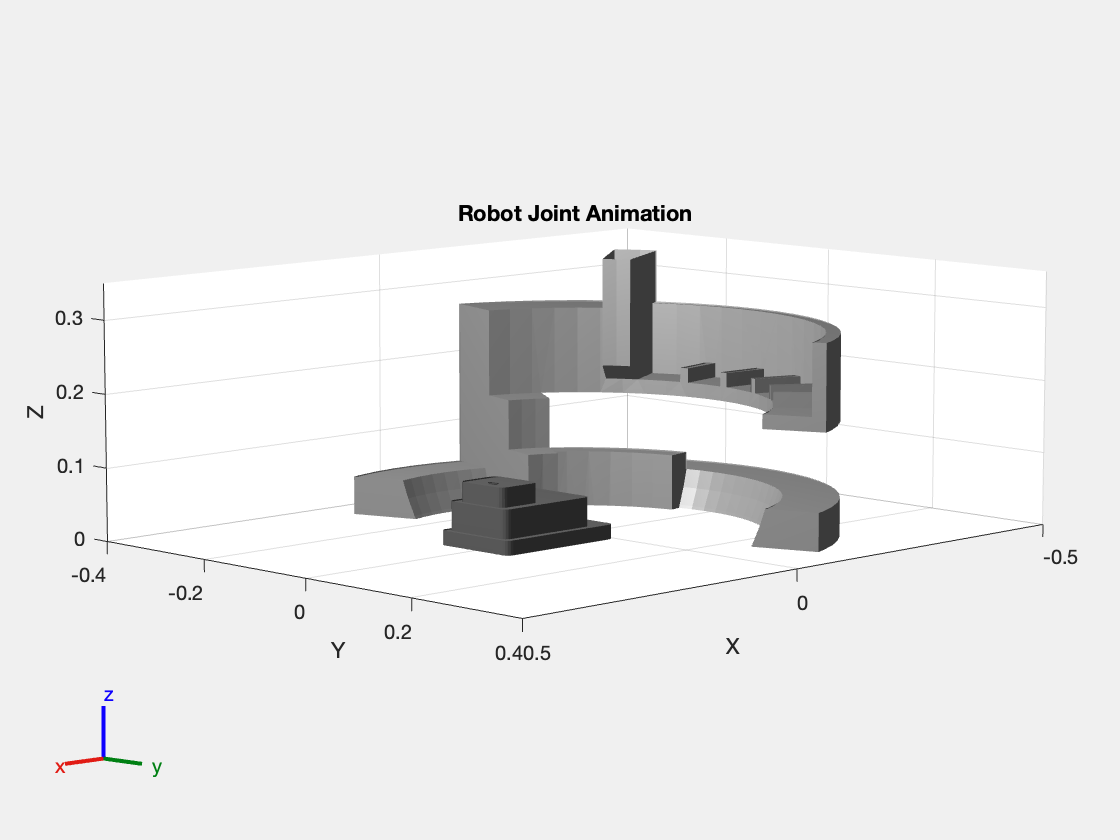


figure;
ax = show(Robot, homeConfiguration(Robot), "Frames", "off");
set(ax, 'ZLim', [0 0.35], 'XLim', [-0.5 0.5], 'YLim', [-0.4 0.4]);
title('Robot Joint Animation');


% Joint names from home configuration
config = homeConfiguration(Robot);
jointNames = {config(1).JointName, config(2).JointName, config(3).JointName};

Index exceeds array bounds.


numJoints = length(jointNames);
angleSteps = 60;
angleRange = 0:angleSteps:360;

for joint1Angle = angleRange
    for joint2Angle = angleRange
        for joint3Angle = angleRange
            config = homeConfiguration(Robot);

            % Correctly set joint positions
            config(1).JointPosition = deg2rad(joint1Angle);
            config(2).JointPosition = deg2rad(joint2Angle);
            config(3).JointPosition = deg2rad(joint3Angle);

            show(Robot, config, "Frames", "off", "Parent", ax);
            set(ax, 'ZLim', [0 0.35], 'XLim', [-0.25 0.5], 'YLim', [-0.25 0.25]);
            drawnow;
            pause(0.0005);
        end
    end
end
